M =     2.3713    1.1548    0.6643


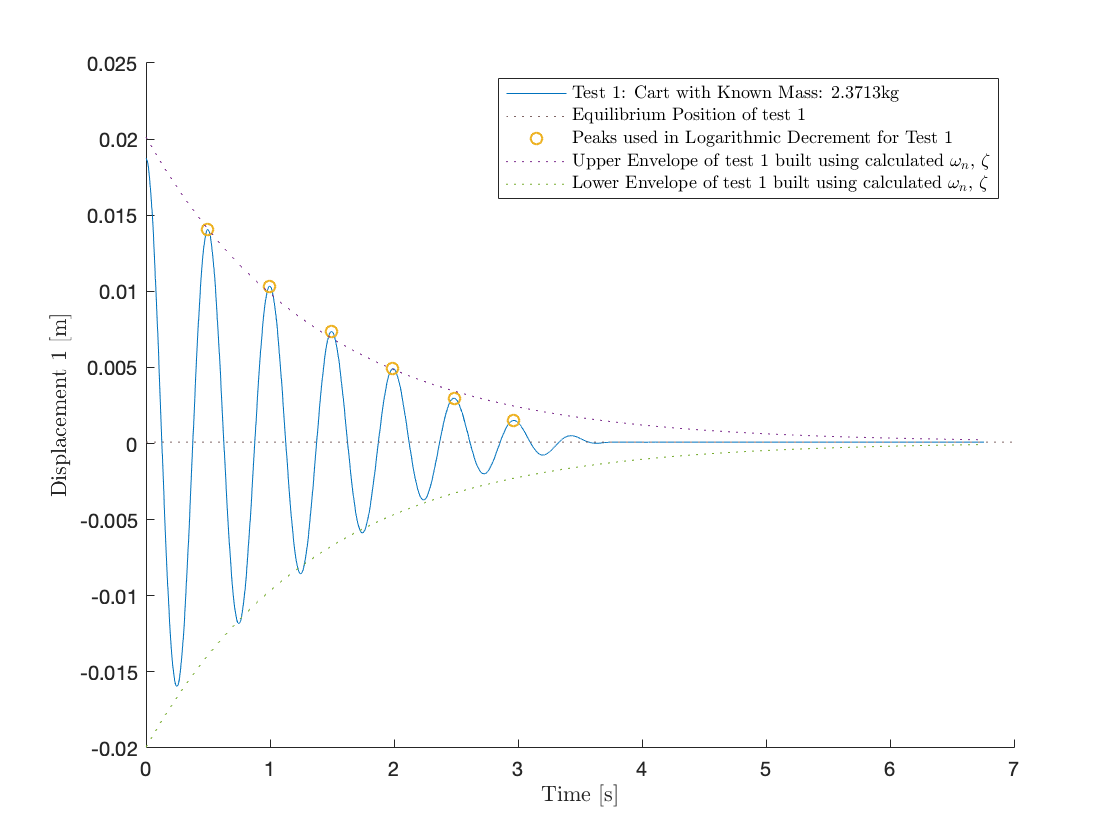

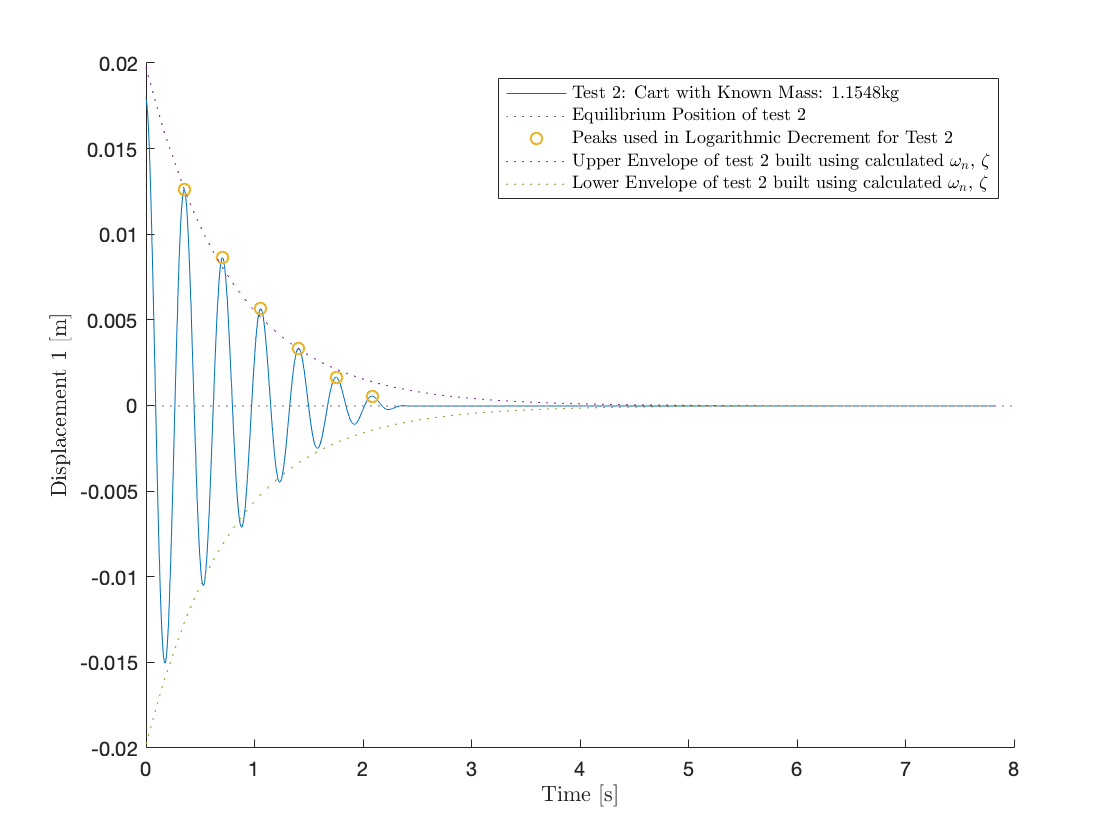

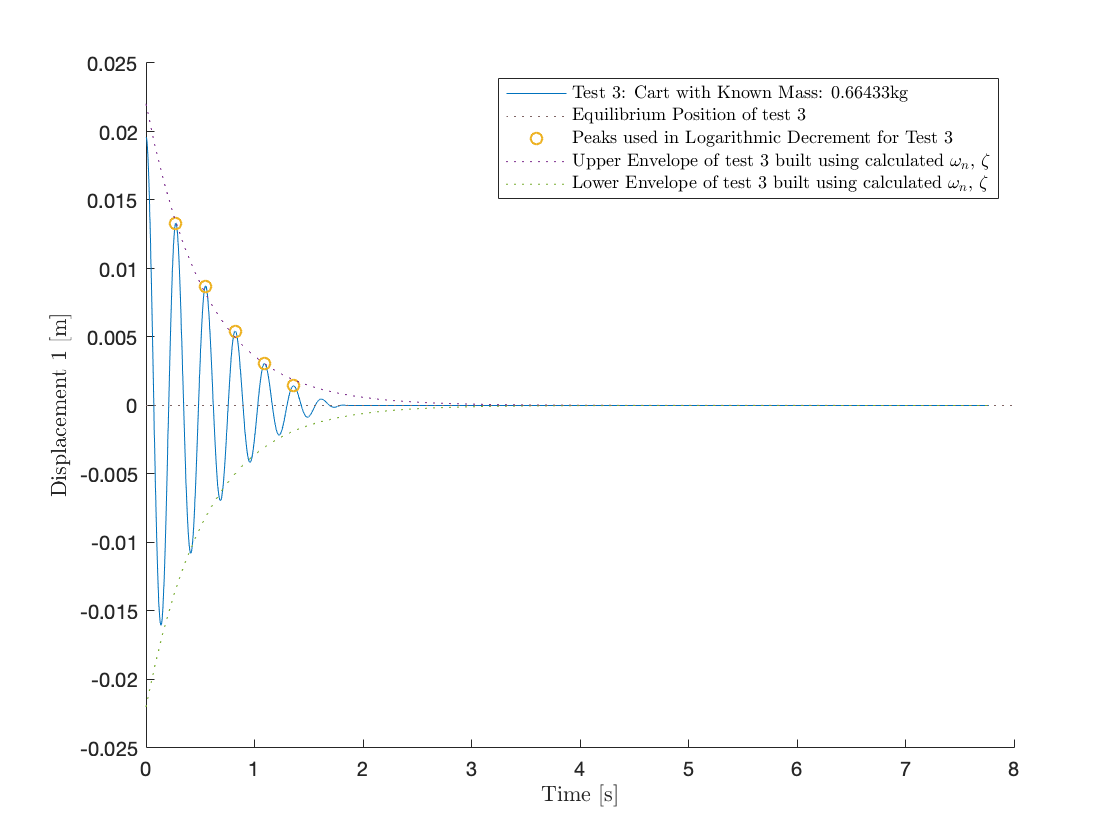

k =   387.0292  380.0525  359.9551


c =     3.4130    2.9266    2.4074


rect_q5_run()

function rect_q5_run()
    % PRIOR KNOWNS:
    % Masses of Blocks [kg]:
    mb1 = 490.5e-3; 
    mb2 = 485.5e-3;
    mb3 = 240.5e-3;
    mb6 = 490.5e-3;
    Mc = mean([0.768, 0.672, 0.553]); % Mean of Cart Masses Determined in Lab 1
    
    % Known Masses for Each Experiment:
    M(1) = Mc + mb1 + mb2 + mb3 + mb6;
    M(2) = Mc + mb1;
    M(3) = Mc
    
    % Perform Logarithmic Decrement on All Experiments:
    [wn(1), z(1)] = multi_logdec("m", "RectData/exp2/3.1/", 1,"test1",M(1)+"kg");
    saveas(gcf, char("Rect_q5-1.png"), 'png');
    [wn(2), z(2)] = multi_logdec("m", "RectData/exp2/3.1/", 2,"test2",M(2)+"kg");
    saveas(gcf, char("Rec_q5-2.png"), 'png');
    [wn(3), z(3)] = multi_logdec("m", "RectData/exp2/3.1/", 3,"test3",M(3)+"kg");
    saveas(gcf, char("Rect_q5-3.png"), 'png');
    
    % Compute All Unknowns:
    k = wn.^2 .* M
    c = 2 .* z .* wn .* M
    mean(k)
    mean(c)
end